## Mooring Module Example

In this example, we'll explore the functionalities of the Mooring module of the Marine and Hydrokinetic Toolkit (MHKiT). As of now, this module primarily supports output from MoorDyn, an innovative tool for simulating the complex dynamics of mooring lines used in marine applications.

The objective will be to analyze the MoorDyn output data of a single mooring line. The steps are:

- **Import Data** - Import the MoorDyn output

- **Lay Length** - Calculate the lay length parameter

- **Visualize** - Create graphical animations

### Importing Data

The first step is to import the MoorDyn output file. This file contains the key data that we'll be analyzing throughout this notebook. If support for other types of output is desired, please raise an issue or reach out to the MHKiT team!

The code below provides paths to two files:

- `fpath` = MoorDyn output file of a single mooring line containing node positions and segment tensions

- `inputfile` = Path to MoorDyn input file that corresponds to the output. This is an optional argument which parses the input parameters and writes them a struct for reference. Note: the input file provided here does not match the output and is only meant for demonstration purposes.

% define the paths
fpath = "./examples/data/mooring/line1_test.out";
inputfile = "./examples/data/mooring/TestInput.MD.dat";
% load in data
[data, input] = read_moordyn(fpath, inputfile)

data = 3581×44 table
    Time     Node0px    Node0py    Node0pz    Node1px    Node1py    Node1pz    Node2px    Node2py    Node2pz    Node3px    Node3py    Node3pz    Node4px    Node4py    Node4pz    Node5px    Node5py    Node5pz    Node6px    Node6py    Node6pz    Node7px    Node7py    Node7pz    Node8px    Node8py    Node8pz    Node9px    Node9py    Node9pz    Node10px    Node10py    Node10pz    Seg1Ten

input = struct with fields:
        LineTypes: [1×10 table]
           Points: [6×9 table]
            Lines: [3×7 table]
    SolverOptions: {7×1 cell}
          Outputs: {'FairTen1'  'FairTen2'  'FairTen3'  'AnchTen1'  'AnchTen2'  'AnchTen3'}


### Calculating the Lay Length with MoorDyn Data

Next, we turn our focus to calculating the 'lay length'. Lay length is the measure of how much of the mooring line is in contact with the seabed. 

To calculate the lay length, we'll use the MoorDyn output data we imported in the previous step. We also need to define two key parameters:

- The `depth` of the seabed, which we've set as -56m for this example. Please note that the seabed depth is considered negative as we're measuring downwards from the sea level.

- The `tolerance`, or the threshold, for determining when a node is deemed to be in contact with the seabed. For this exercise, we'll use a tolerance of 0.25m. The selection of a suitable tolerance value depends on various factors including the resolution of your data and the specifics of your application.

We use the `lay_length` function for this calculation, which will yield an array representing the lay length of the mooring line at each time step. Let's execute the function:

depth = -56; % meters
tolerance = 0.25; % meters
laylength = lay_length(data, -56, 0.25)

laylength =    45.0010
   45.0010
   45.0010
   45.0010
   45.0010
   45.0010
   45.0010
   45.0010
   45.0010
   45.0010


Additionally we can use this information to get an average lay length for the whole time period.

fprintf('The average lay length of the mooring line is: %.1f meters', mean(laylength))

The average lay length of the mooring line is: 45.0 meters

### Visualizing Mooring Line Dynamics with Graphics

After calculating the lay length, let's progress to the final step of our journey: visualization. The mooring module within MHKiT provides tools to create interactive, informative graphics that can help us visualize and better understand the behavior of the mooring line.

However, to keep things performance-friendly, we will first slice our initial data down to a 10-second window. This reduces computational demand while still providing a useful snapshot of our mooring line's dynamics.

With our data subset ready, we can create a 3D animation of the mooring line using the `plot_mooring_animate`. 

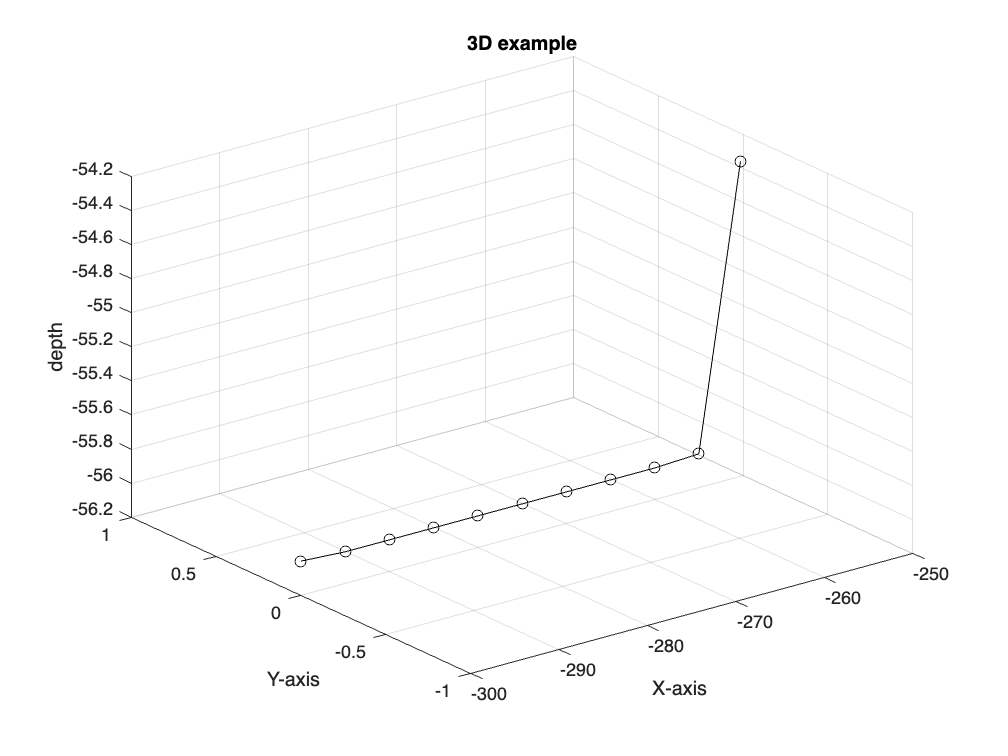

plot_mooring_animate(data(data.Time<10, :), '3D', 0.05, ...
    'xlabel','X-axis','ylabel','Y-axis','zlabel','depth','title','3D example')

In this simplified example, the mooring line is constrained from moving along the y-axis. Since there is no motion along the y-axis, it would actually be easier to view the animation in 2D instead. This can be accomplished with the `plot_mooring_animate` function specifying dimension=`'2D'`.

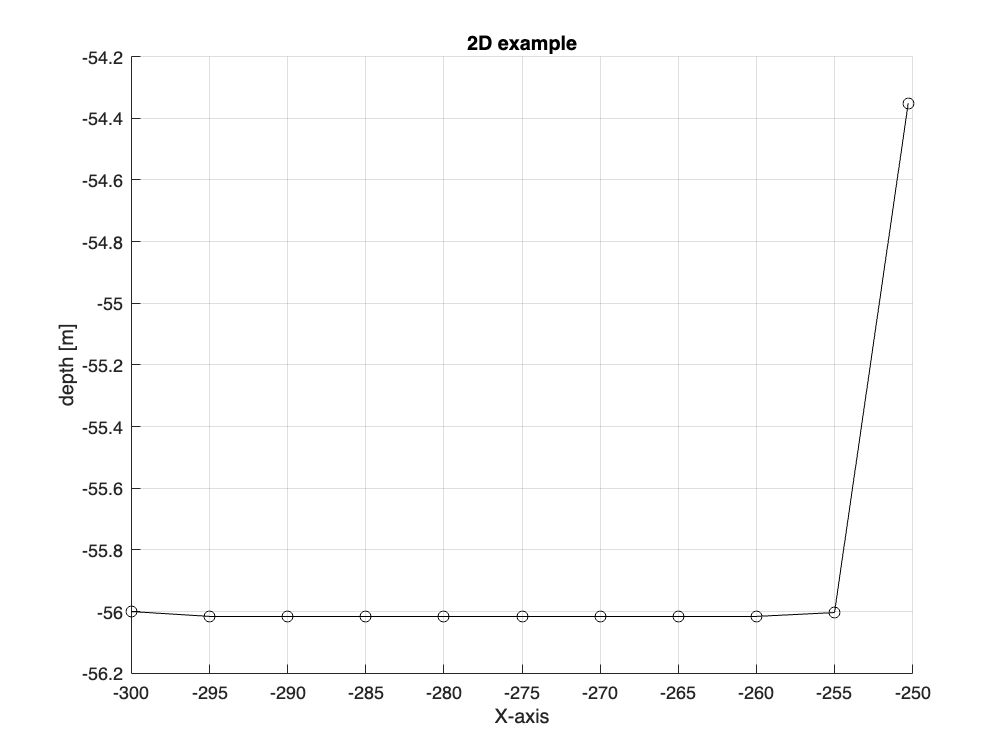

plot_mooring_animate(data(data.Time<10, :), '2D', 0.05, ...
    'xlabel','X-axis','ylabel','depth [m]','title','2D example')

Through these graphical representations, we can gain a more intuitive understanding of how the mooring line interacts with the surrounding marine environment over time.

### Summary and Conclusion

In this notebook, we walked through the MHKiT Mooring module learning how to utilize MHKiT in conjunction with MoorDyn output to analyze the dynamics of a single mooring line.

We used the `read_moordyn` function to bring this data into Matlab, preparing it for further analysis. Next, we calculated the 'lay length' of our mooring line using the `lay_length` function, obtaining an array representing the lay length at each time step. Finally, we visualized 2D and 3D animations of the mooring line's behavior over a 10-second period using the `plot_mooring_animate` function.

We hope that this example serves as a valuable guide to employing the MHKiT Mooring module and MoorDyn analyses.

Thank you for your interest in MHKiT! We encourage you to continue to open an issue or pull request if you have any feedback or expansions which would help you improve your mooring data analysis.